# Motor parametric identification

The goal of this code is identifying the motor parameters of a DC motor using a generic simulink model and matlab optimization function using as cost function the quadratic error

## Load input output data for parametric identification

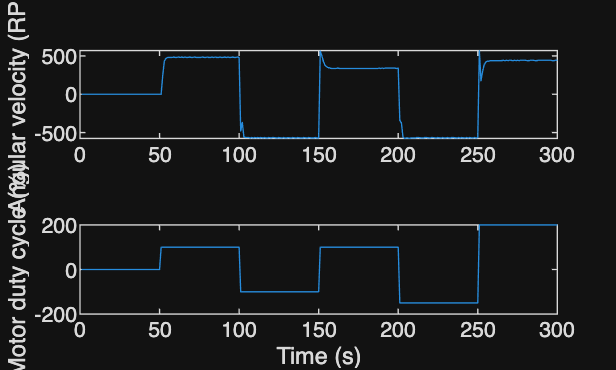

load('/Users/jairoviola/Documents/MATLAB/DT_COSMOS/DCMotorIO.mat')

PWM=BMInput(1:300,2);
RPM=BMOut(1:300,2);
ts=BMInput(2,1);
time=BMInput(1:300,1);

inputVector=[time,PWM];

sysDataIdent=iddata(RPM,PWM,ts);

figure()
subplot(2,1,1)
plot(RPM)
ylabel('Angular velocity (RPM)')
subplot(2,1,2)
plot(PWM)
ylabel('Motor duty cycle (%)')
xlabel('Time (s)')

## system initial condition parameters for the DC motor identification

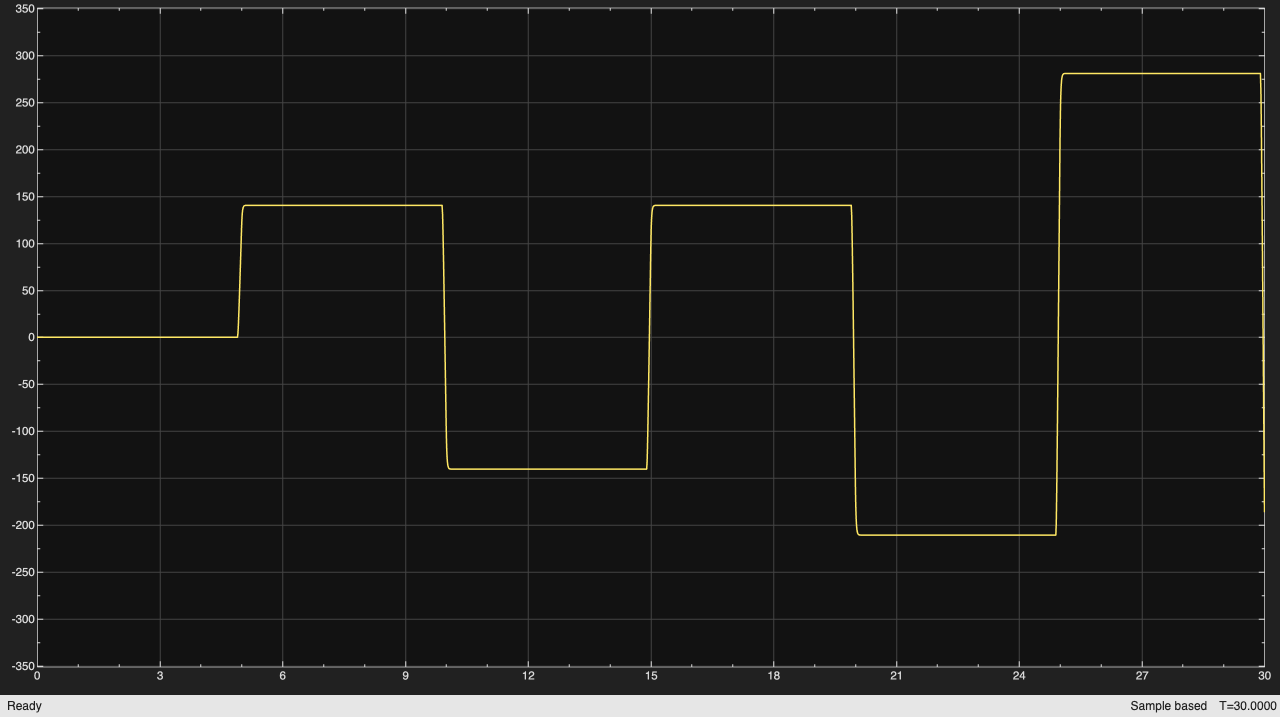

R = 4;
L = 2.75E-6;
K = 0.0274;
J = 3.2284E-6;
b = 3.5077E-6;
VCC=10;
gamma=1;
open("Motor_Pos.slx");
sim("Motor_Pos.slx")

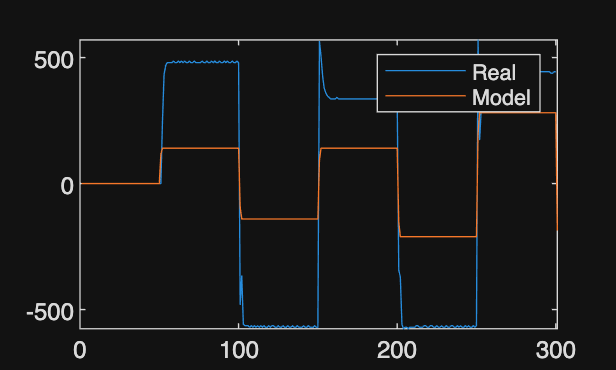

simulatedRPM=simout(:,1);
figure()
plot(RPM)
hold on
plot(simulatedRPM)
legend('Real','Model')

 
 Iteration   Func-count         f(x)         Procedure
     0            1          1075.76         
     1            8           105.37         initial simplex
     2            9           105.37         reflect
     3           10           105.37         reflect
     4           12          39.9203         reflect
     5           13          39.9203         reflect
     6           14          39.9203         reflect
     7           15          39.9203         reflect
     8           16          39.9203         reflect
     9           18          39.9203         contract inside
    10           20          39.9203         contract inside
    11           22          20.6046         contract inside
    12           23          20.6046         reflect
    13           24          20.6046         reflect
    14           26          20.6046         contract inside
    15           28          20.6046         contract inside
    16           30          15.3333         contract 

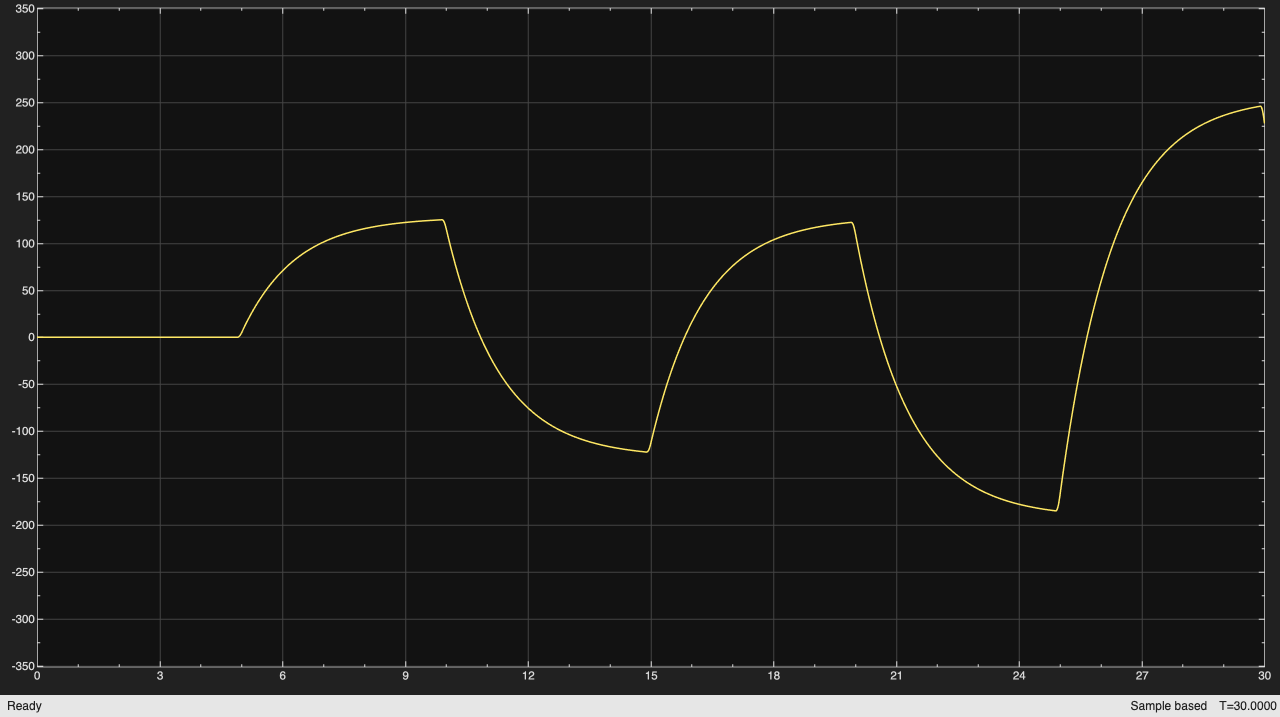

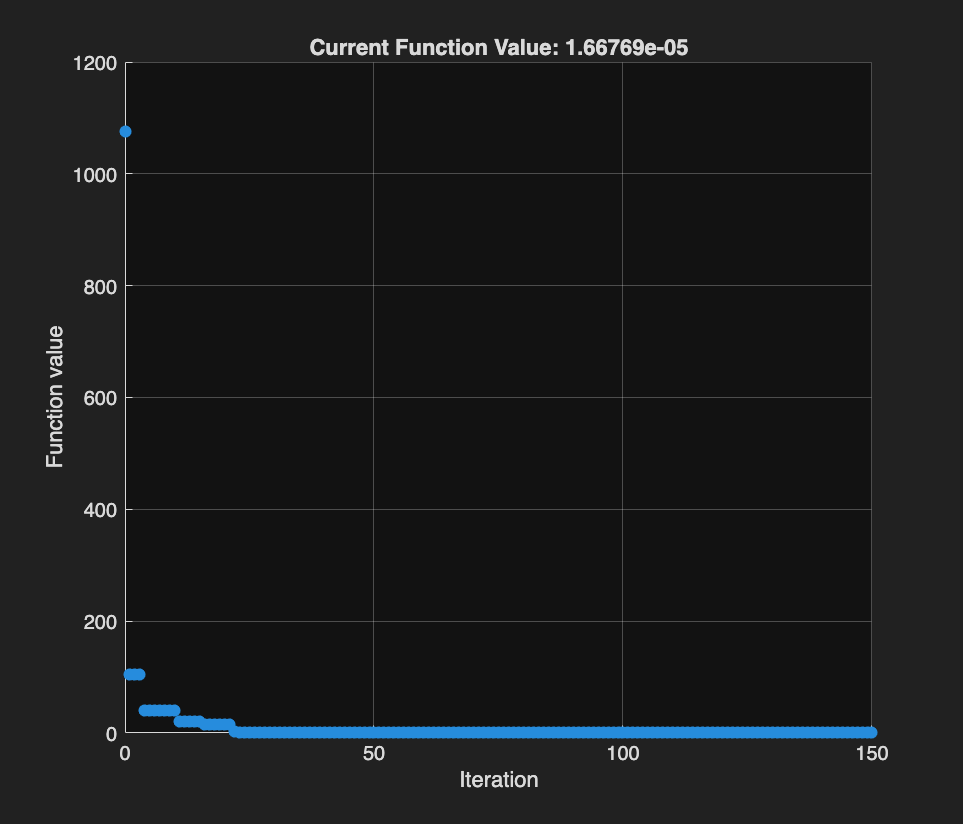

x =     4.2373    0.0000    0.0100    0.0001    0.0000    9.1709    3.0008


%unconstrained Nelder-Mead Optimization using fminsearch function

%maximum number of iterations
maxiter=150;

%tolerance
tolx=1e-6;

% define initial conditions
x0 = [R,L,K,J,b,VCC,gamma];
%boundaries for NM
lb = [1e-7, 1e-7, 1e-7, 1e-7, 1e-7,0,3];
ub = [5, 1e-2, 1e-2,1e-2,1e-2,20,7];
%option vector to select which properties to display on the results
options = optimset('Display','iter','MaxIter',maxiter,'TolX',tolx,'PlotFcns',@optimplotfval);
%perform optimization using fminsearchbnd
x = fminsearchbnd(@FOPDT_sysID,x0,lb,ub,options)

## Compare adjusted and real response

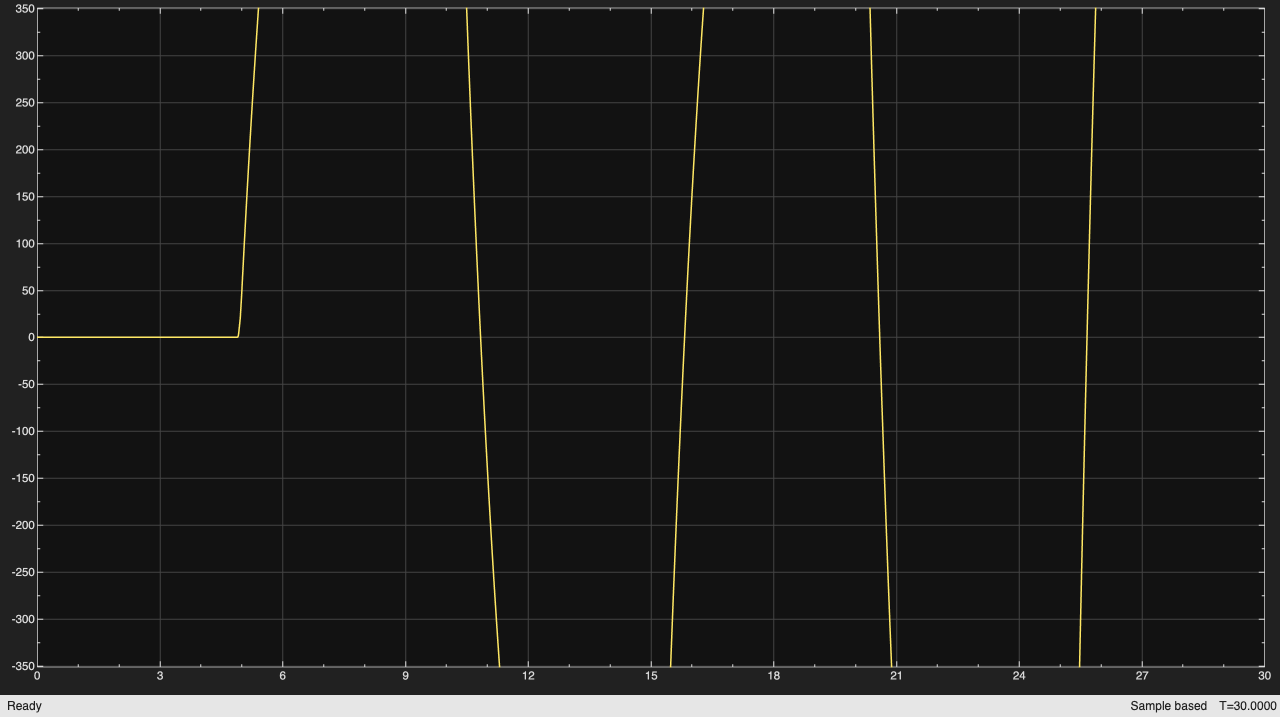

R = x(1);
L = x(2);
K = x(3);
J = x(4);
b = x(5);
gamma=x(6);
sim("Motor_Pos.slx")

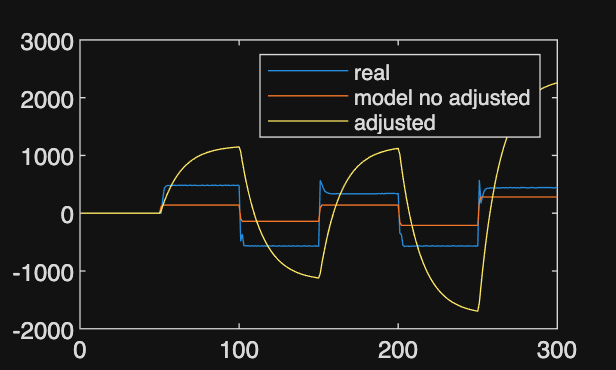

simulatedRPMAdjusted=simout(1:300,1);

figure()
plot(RPM(1:300))
hold on
plot(simulatedRPM(1:300))
plot(simulatedRPMAdjusted)
legend('real','model no adjusted','adjusted')